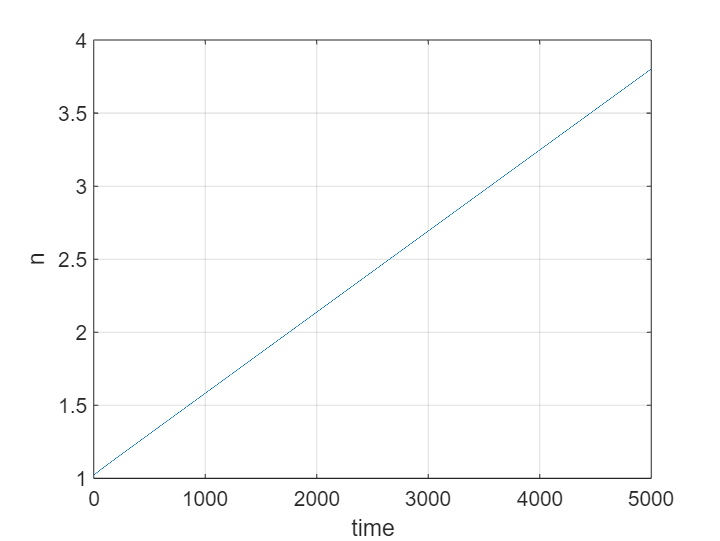

global NI;
global NX;
global Tbulk;
global modtemp;

NI=0;
NX=0;


% Thermla Hydrualic values:
mass_flow_in= 255; %kg/s;
mass_flow_out= 300; %hg/s;
Specifheat_water= 4.186; %J/kgm (fix units);

% Point reactor kinetics 6 groups of delayed neutrons
beta = [0.00021; 0.00141; 0.00127; 0.00255; 0.00074; 0.00027]; % Taken from Glasstone and Sesonske
betasum = sum(beta);
 
% Initial consitions
Tbulk = 34;
c0 = zeros(6, 1);
n0 = 1;
tspan = [0, 5000];
nc0 = [n0; c0];
[t, nc] = ode45(@(t,nc) kinetics(t,nc,beta,betasum, NI, NX, Tbulk), tspan, nc0);
n = nc(:,1);
c = nc(:, 2:7);
plot(t,n),grid,
xlabel('time'), ylabel('n')

function dncdt = kinetics(t,nc,beta,betasum, NI, NX, Tbulk)
        L = 0.0001;
        lam = [0.0126; 0.0337; 0.111; 0.301; 1.14; 3.01];
        n = nc(1);
        c = nc(2:7);
        modtemp = avgmodtemp(Tbulk);
        Tf = Fueltemperature(Tbulk);
        rho = master_reactivity_function(n, t, NI, NX, modtemp, Tf);
        dndt = (rho - betasum)* n / (L + sum(lam.*c));
        dcdt = beta*n/L - lam.*c;
        Tbulk = bulktemp(Tbulk); %will update to power put in dndt for argument
        
        dncdt = [dndt; dcdt];        
end
function [reac_eff_Xe, NI, NX] = xenon_buildup(power, time, NI,NX)
    ids=24120;            % Iodine_decay_constant [s]
    xds=33120;            % Xenon_decay_constant [s]
    ify=0.0629;           % Iodine_fission_yield [%]
   
    nu=2.3;               % neutrons per fission 
    xmacs=2.75*10^(-18);  % Xenon_microscopic_abs_cross_section m[cm^2]

    mfcs=0.0487;         % macroscopic_fission_cross_section_U235 [cm^2]
    mifcs=585*10^(-24);    % microscopic_fission_cross_section_U235 [cm^2]
    volume_of_core=5.13*10^27; % [atoms/core]
    E_r=200.7*10^6*1.6*10^(-19);                            % Energy per fission (estimate) converted from MeV to W [W/fisison]
    
    
    iodine_pop=NI;   
    xenon_pop=NX;
   

 

    neutron_flux=power*(10^6)/((mifcs)*E_r*volume_of_core);  % 'Mystery number' is a conversion from MW to W result is in neutrons cm^-2 s^-1
    
    NI =((ify)*(mfcs)*(neutron_flux)-(1/ids)*(iodine_pop))*(time);                              % Determines Iodine population
    
    iodine_pop= NI;

    NX =((1/ids)*(iodine_pop)-(1/xds)*(xenon_pop)-(xmacs)*(xenon_pop)*(neutron_flux))*(time);  % Determines Xenon population

    xenon_pop = NX;

    reac_eff_Xe = (xmacs*xenon_pop)/(mfcs*nu);  % Calcualtes effect on reactivity from Xenon population
    
end 
   

function cr_reac_eff = control_rod_reac() % CAN BE FURTHER REFINED, roughly dtermines reactivity; tables with values will later be added for better accuracy
    reg_rod=linspace(0,3.19, 1001);
    safety_rod=linspace(0,2.15,1001);
    shim_rod=linspace(0,2.56,1001);
    trans_rod=linspace(0,2.68,1001);
    reg_height=21;
    safety_height=25;
    shim_height=56;
    trans_height=78;
    cr_reac_eff=(reg_rod(reg_height*10)+safety_rod(safety_height*10)+shim_rod(shim_height*10)+trans_rod(trans_height*10))*0.0075;
    

end 



 

function reactivity = master_reactivity_function(power, time, NI, NX, modtemp, T_avg_f)
        reactivity=control_rod_reac()-xenon_buildup(power, time, NI, NX)+ mod_reactivity(modtemp)+fuel_reactivity(T_avg_f);
        
end 

function Mod_Reactivity_R = mod_reactivity(T_avg_in_core)
T = T_avg_in_core; % in celcius
B_eff = 0.0075;
MTC = -0.0072; % dollars per celcius
MR_D = MTC*T; % moderator reactivity in cents
Mod_Reactivity_R = MR_D*B_eff;
end 


function Fuel_Reactivity_R = fuel_reactivity(T_avg_fuel_in_core)
Fuel_Reactivity_R = 1.072*10^-5*(T_avg_fuel_in_core)+2.49*10^-3; % in celcius
end 

function PrimaryWaterTout = HeatExchanger(Tbulk)
    PrimaryWaterTout = Tbulk - ((54.19*(30.5-25.5))/(39.12*4.2));   
end

function Tout = coreout(Tbulk)
    Tout = 21 + HeatExchanger(Tbulk);
end


function Tf = Fueltemperature(TBulk)
    Tf = 558.895 + coreout(TBulk);
end

function modtemp = avgmodtemp(Tbulk)
    modtemp = (HeatExchanger(Tbulk) + coreout(Tbulk)) / 2;
end


function TB = bulktemp(Tbulk)
    TB = (178.3 * coreout(Tbulk) + (341.7 * HeatExchanger(Tbulk))) / 520;
    Tbulk = TB;
end









